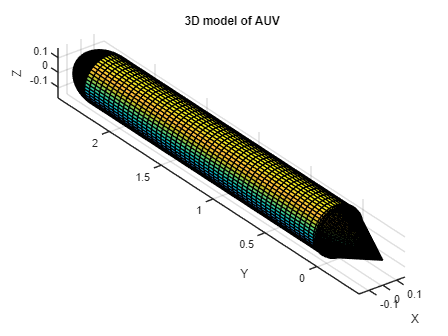

% Define the radius and length of the nose cone
r_max = 0.27;      % maximum radius
L_tail = 0.29;    % length of the tail
semi_angle = 24.5;  % nose cone semi angle in degrees
bluntness = 3.5;    % fraction of cone length for the flat section

% Define the radius and length of the cylinder
r_cyl = 0.165;     % radius of the cylinder
L_cyl = 1.5;      % length of the cylinder

% Define the radius and length of the nose cap
r_cap = 0.165;    % radius of the cap
L_cap = 0.66;      % length of the cap

% Define the number of points to use for the surfaces
n = 50;

% Calculate the nose cone base radius
r_base = r_max / tand(semi_angle);

% Define the angles and heights for the surface of the cone
theta_cone = linspace(0,2*pi,n);
z_cone = linspace(0,L_tail,n);
[theta_cone,z_cone] = meshgrid(theta_cone,z_cone);

% Calculate the radius at each point along the cone height
r_cone = r_base - z_cone * (r_base / L_tail);

% Add a flat section to the tip of the cone
flat_length = L_tail * bluntness;
flat_idx = find(z_cone >= L_tail-flat_length);
r_cone(flat_idx) = r_cone(flat_idx(1)) * (1 - (z_cone(flat_idx) - (L_tail-flat_length)) / flat_length);

% Create the surface of the nose cone
x_cone = r_cone .* cos(theta_cone);
y_cone = r_cone .* sin(theta_cone);
z_cone =  -(z_cone -0.06*L_tail); % shift nose cone downwards

% Define the angles and heights for the surface of the cylinder
theta_cyl = linspace(0,2*pi,n);
z_cyl = linspace(0,L_cyl,n);
[theta_cyl,z_cyl] = meshgrid(theta_cyl,z_cyl);

% Create the surface of the cylinder
x_cyl = r_cyl .* cos(theta_cyl);
y_cyl = r_cyl .* sin(theta_cyl);
z_cyl = z_cyl;

% Define the angles and heights for the surface of the nose cap
theta_cap = linspace(0,2*pi,n);
phi_cap = linspace(0,pi/2,n);
[theta_cap,phi_cap] = meshgrid(theta_cap,phi_cap);

% Create the surface of the nose cap (semi-ellipsoid)
x_cap = r_cap * sin(phi_cap) .* cos(theta_cap);
y_cap = r_cap * sin(phi_cap) .* sin(theta_cap);
z_cap = z_cyl(end) + r_cap * cos(phi_cap);

% Shift the nose cone so that its base aligns with the open base of the cylinder
z_cone = z_cone;

% Define the rotation angles
theta_x = 90; % rotation angle around x-axis in degrees
theta_y = 180; % rotation angle around y-axis in degrees
theta_z = 0; % rotation angle around z-axis in degrees

% Convert the angles to radians
theta_x = theta_x * pi / 180;
theta_y = theta_y * pi / 180;
theta_z = theta_z * pi / 180;

% Define the rotation matrices
Rx = [1, 0, 0; 0, cos(theta_x), -sin(theta_x); 0, sin(theta_x), cos(theta_x)];
Ry = [cos(theta_y), 0, sin(theta_y); 0, 1, 0; -sin(theta_y), 0, cos(theta_y)];
Rz = [cos(theta_z), -sin(theta_z), 0; sin(theta_z), cos(theta_z), 0; 0, 0, 1.5];

% Calculate the composite rotation matrix
R = Rx * Ry * Rz;

% Apply the rotation to the coordinates of each surface
x_cone_rot = zeros(size(x_cone));
y_cone_rot = zeros(size(y_cone));
z_cone_rot = zeros(size(z_cone));

x_cyl_rot = zeros(size(x_cyl));
y_cyl_rot = zeros(size(y_cyl));
z_cyl_rot = zeros(size(z_cyl));

x_cap_rot = zeros(size(x_cap));
y_cap_rot = zeros(size(y_cap));
z_cap_rot = zeros(size(z_cap));

for i = 1:numel(x_cone)
v = [x_cone(i), y_cone(i), z_cone(i)]';
v_rot = R * v;
x_cone_rot(i) = v_rot(1);
y_cone_rot(i) = v_rot(2);
z_cone_rot(i) = v_rot(3);
end

for i = 1:numel(x_cyl)
v = [x_cyl(i), y_cyl(i), z_cyl(i)]';
v_rot = R * v;
x_cyl_rot(i) = v_rot(1);
y_cyl_rot(i) = v_rot(2);
z_cyl_rot(i) = v_rot(3);
end

for i = 1:numel(x_cap)
v = [x_cap(i), y_cap(i), z_cap(i)]';
v_rot = R * v;
x_cap_rot(i) = v_rot(1);
y_cap_rot(i) = v_rot(2);
z_cap_rot(i) = v_rot(3);
end

% Plot the AUV
figure(2)
surf(x_cone_rot, y_cone_rot, z_cone_rot)
hold on
surf(x_cyl_rot, y_cyl_rot, z_cyl_rot)
surf(x_cap_rot, y_cap_rot, z_cap_rot)
axis equal
xlabel('X')
ylabel('Y')
zlabel('Z')
title('3D model of AUV')